Филимонов Степан РЛ6-31

Лабараторная номер 5

Задача:

Необходимо отрисовать для электрона локализованного в одномерной  бесконечно глубокой яме 10 нм график пси функции от координаты (для  основного состояния и 24-го возбужденного). Сравнить графики полученный  на основе аналитического решения уравнения Шрёдингера с результатами  работы встроенной MATLAB-функции eig.

Фото задания:

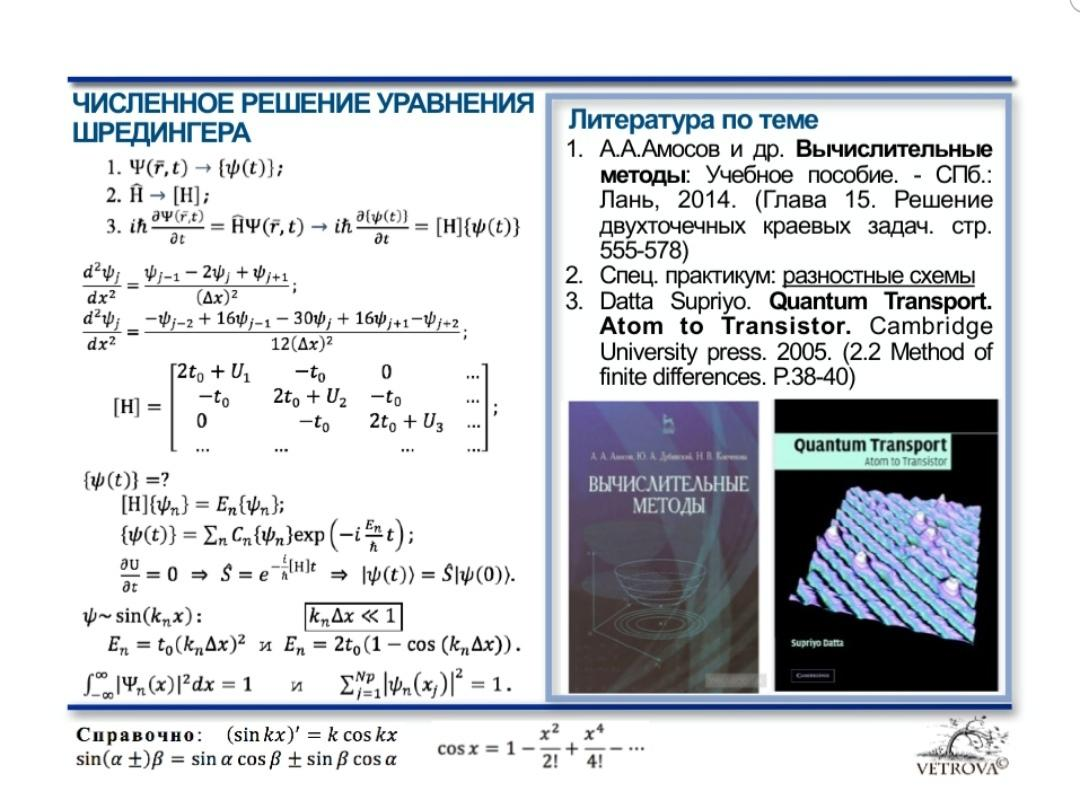

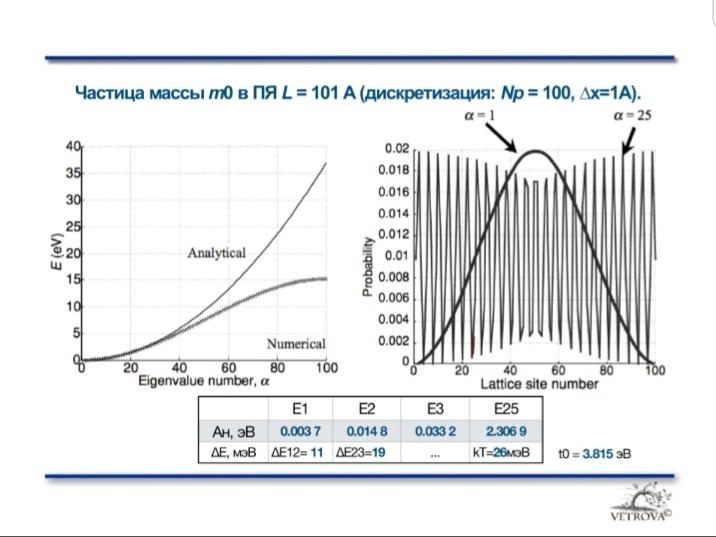

Теория:

**Квантовая яма с бесконечными стенками** — область пространства размером порядка длины волны де Бройля рассматриваемой частицы (хотя бы в одном направлении), вне которой потенциальная энергия *U* бесконечна. Иногда данную область называют «ящиком»

**Двухточечная краевая задача** - это задача отыскания решения  обыкновенного дифференциального уравнения или системы обыкно­венных дифференциальных уравнений на отрезке $а\le x\le б$, в которой дополнительные условия на решение налагаются в двух точках а и б - "краях" отрезка (отсюда - и название задачи). 

Решение:

Численное решение уравнения Шредингера(стационарного)


$$-\frac{\hbar }{2m}\Delta \psi \left(x\right)+U\left(x\right)\psi \left(x\right)=E\psi \left(x\right)$$


- 
$$\Psi \left(\bar{r,t} \right)\to \left\lbrace \psi \left(t\right)\right\rbrace$$


- $\hat{H} \to \left\lbrack H\right\rbrack$;

- 
$$i\hbar \frac{\partial }{\partial t}\Psi \left(\bar{r,t} \right)=\hat{H} \Psi \left(\bar{r,t} \right)\to i\hbar \frac{\partial }{\partial t}\left\lbrace \psi \left(t\right)\right\rbrace =\left\lbrack H\right\rbrack \left\lbrace \psi \left(t\right)\right\rbrace$$


Из


$$\left\lbrace \begin{array}{ll}
\psi_{i+1} =\psi_i +\Delta x\frac{d}{\mathrm{d}x}\psi_i +\frac{\Delta x^2 }{2!}\frac{d^2 }{\mathrm{d}x^2 }\psi_i +\frac{\Delta x^3 }{3!}\frac{d^3 }{\mathrm{d}x^3 }\psi_i +\frac{\Delta x^4 }{4!}\frac{d^4 }{\mathrm{d}x^4 }\psi_i +\ldotp \ldotp \ldotp  & \\
\psi_{i-1} =\psi_i -\Delta x\frac{d}{\mathrm{d}x}\psi_i +\frac{\Delta x^2 }{2!}\frac{d^2 }{\mathrm{d}x^2 }\psi_i -\frac{\Delta x^3 }{3!}\frac{d^3 }{\mathrm{d}x^3 }\psi_i +\frac{\Delta x^4 }{4!}\frac{d^4 }{\mathrm{d}x^4 }\psi_i +\ldotp \ldotp \ldotp  & 
\end{array}\right.$$


Получим:

$\frac{\psi_{i+1} -2\psi_i +\psi_{i-1} }{\Delta x^2 }=\frac{d^2 }{\mathrm{d}x^2 }\psi_i \Longrightarrow$ это трехточечная апроксимация оператора 2-ой производной , где


$$\mathrm{dx}=\frac{L}{N_p +1}$$


Подставим его:


$$-\frac{\hbar }{2m}\left\lbrack \frac{\psi_{i+1} -2\psi_i +\psi_{i-1} }{\Delta x^2 }\right\rbrack +U_i \psi_i =E_i \psi_i$$


Матрицой этого уравнения будет

$\left\lbrack H\right\rbrack =\left\lbrack \begin{array}{cccc}
2x_0 +U_1  & -x_0  & 0 & \ldotp \ldotp \ldotp \\
-x_0  & 2x_0 +U_2  & -x_0  & \ldotp \ldotp \ldotp \\
0 & -x_0  & 2x_0 +U_3  & \ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack$, где $x_0$это константанта, равная $x_0 =\frac{\hbar^2 }{2m}*\frac{1}{{\mathrm{dx}}^2 }$,$U_i$ - матрица увеличивающая высоту, в нашей задаче = 0, по этому при вычислении учитывотся не будет

Аналитическое решение $\Upsilon =\sin \left(\pi \frac{\textrm{condition}}{L}x\right)$, следует из $k=\frac{\textrm{condition}*\pi }{L}$ и $\psi \left(x\right)=\textrm{Asin}\left(\textrm{kx}\right)\textrm{dx}$, в нашем случае $A=\sqrt{\frac{2}{L}}$.

Энергию состояния, описываемого волновой функцией $\psi_n =C_n \sin \left(n\frac{\pi x}{L}\right)$, получим подставив $k_n =n\frac{\pi }{L}$ в $E=\frac{\hbar }{2m}k^2$:

                                                 
$$E_n =\frac{n^2 \hbar^2 \pi^2 }{2mL^2 }$$


,где *n* - номер орбитали, $\hbar$ - постоянная Планка-Дирка, *m* - масса частицы ( по условию $m=\textrm{meff}*m_0$, *L* - ширина потенциальной ямы(нм).

$\Delta E=E_{n+1} -E_n$.

  $E_n =\frac{n^2 \hbar^2 \pi^2 }{2mL^2 }$; $\textrm{kL}=\pi n$(плотность состояния) из этого следует, что ${\Delta E}_{n,n+1} =\frac{\hbar^2 \pi^2 }{2mL^2 }\left({\left(n+1\right)}^2 -n^2 \right)=\textrm{kT}$, $\left({\left(n+1\right)}^2 -n^2 \right)$ = 3, т.к. n = 1. Тогда


$$L=\hbar \pi \sqrt{\frac{3}{2m*k*T}}$$


Код Matlab:

cla reset;
hold on;
L = 101 * 1e-10; 
[Phk, En, x0] = matrixSchrodinger(L); %*(см. ниже)

- **Задание 1: **получение нормы энергии

normal_energy = norma_energy_get(Phk)

normal_energy =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


- **Задание 2:** построение графиков аналитического решения и результата вычесления встроенной MATLAB-функции eig

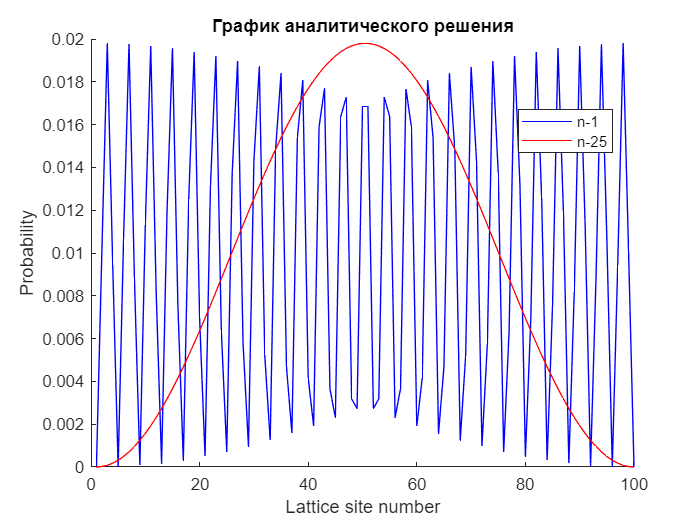

Xn = 1:100; 
plot(Xn, Ytheoretically(25, L),"Color",'blue');
plot(Xn, Ytheoretically(1, L),"Color",'red'); %*(см. ниже)
title('График аналитического решения');
legend('n-1','n-25','Location',"best");
xlabel('Lattice site number');
ylabel('Probability');
hold off;

plot(Xn, abs(Phk(1:end, 1)).^2,"Color",'red');
hold on;
plot(Xn, abs(Phk(1:end, 25)).^2,"Color",'blue'); 
title('График результата вычесления встроенной MATLAB-функции eig');
legend('n-1','n-25','Location',"best");
xlabel('Lattice site number');
ylabel('Probability');

- **Задание 3:** построение энергитических графиков аналитического решения и результата вычесления встроенной MATLAB-функции eig

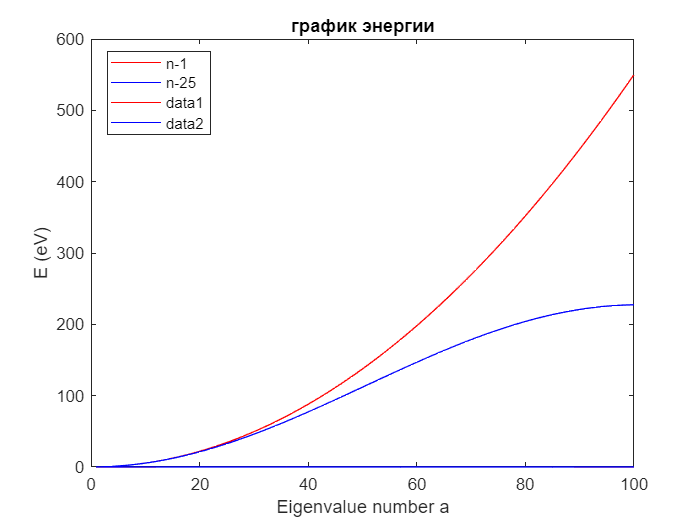

Et1 = Etheoretically(Xn, L); %*(см. ниже)
plot(Xn, Etheoretically(Xn, L),"Color",'red');
hold on;
plot(Xn, En,"Color",'blue');
title('график энергии')
xlabel('Eigenvalue number a');
ylabel('E (eV)')
hold off;

- **Задание 4:** таблица

load("constans.mat","J2eV","kT");
ee = [Et1(1) Et1(2) Et1(3) Et1(25)]

ee =     0.0550    0.2201    0.4952   34.3863


Et1 = Et1.*1e3;
dE=[(Et1(2)-Et1(1)) (Et1(3)-Et1(2)) (Et1(4)-Et1(3)) kT*10^3]

dE =   165.0542  275.0903  385.1264   25.8520


dE = int8(dE)

dE = 1×4 int8 row vector
   127   127   127    26


x0 = x0 * J2eV

x0 = 56.8654

- **Задание 5:** таблица L = 201A

L = 201 * 1e-10; 
[Phk, En2, x0] = matrixSchrodinger(L); 
Et = Etheoretically(Xn, L);
ee = [Et(1) Et(2) Et(3) Et(25)]

ee =     0.0139    0.0556    0.1250    8.6823


Et = Et.*1e3;
dE=[(Et(2)-Et(1)) (Et(3)-Et(2)) (Et(4)-Et(3)) kT*10^3]

dE =    41.6751   69.4586   97.2420   25.8520


dE = int8(dE)

dE = 1×4 int8 row vector
   42   69   97   26


x0 = x0 * J2eV

x0 = 14.3582

- **Вывод по заданию 4 и 5:**

- **результаты на разных энергиях**

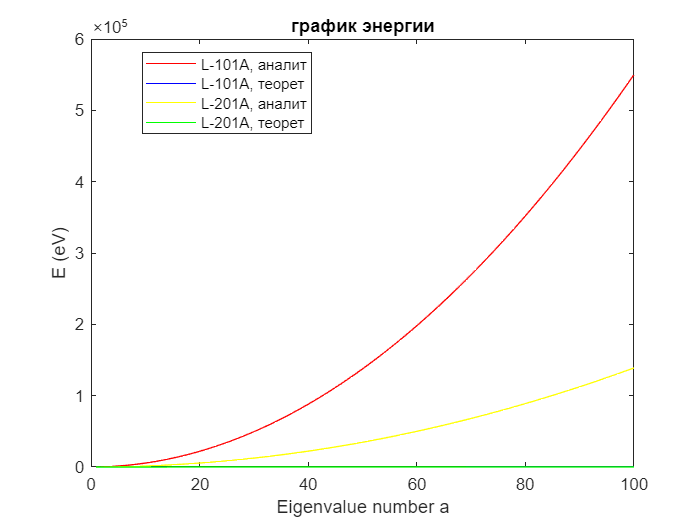

plot(Xn, Et1,"Color",'red');
hold on;
plot(Xn, En,"Color",'blue');
plot(Xn, Et,"Color",'yellow');
plot(Xn, En2,"Color",'green');
legend('L-101A, аналит','L-101A, теорет','L-201A, аналит','L-201A, теорет',"Location","best")
title('график энергии')
xlabel('Eigenvalue number a');
ylabel('E (eV)')
hold off;

- **Время:**

datetime('now')

ans = datetime
   04-Dec-2021 09:32:21


*Функция создания графика: 

function yt = Ytheoretically(n, L)
 Np = 100; 
 dx = L / (Np + 1);
 r = 2 / L;
 X = linspace(0, L, 100);
 yt = r * dx * abs(sin((pi * n / L)  * X)).^2;
end

function et = Etheoretically(n, L)
 load("constans.mat","m0","hbar","J2eV");
 et = (pi * hbar * n / L).^2/(2 * m0 * 0.067) * J2eV;
end 

function [Y, En, x0] = matrixSchrodinger(L)
 load("constans.mat","m0","hbar","J2eV");
 Np = 100; 
 dx = L / (Np + 1);
 x0 = (hbar ^ 2) / (2 * m0 * 0.067 * dx ^ 2);
 H = zeros(Np);
 H(1, 1) = 2 * x0;
 H(1, 2) = -x0;
 for r = 2:Np
   for c = 1:Np
     if and(and(r ~= 1, r ~= Np),r == c)
       H(r, c) = 2 * x0;
       H(r, c - 1) = -x0;
       H(r, c + 1) = -x0;
     end
   end
 end
 H(Np, Np) = 2 * x0;
 H(Np, Np - 1) = -x0;
 [Y, En] = eig(H); % вернем диагональную матрицу
 En = diag(En) * J2eV;
end

function ne = norma_energy_get(Phk)
 ne = 0; 
 for c = 1:100
    ne = ne + abs(Phk(1:end, c)).^2;
 end
end